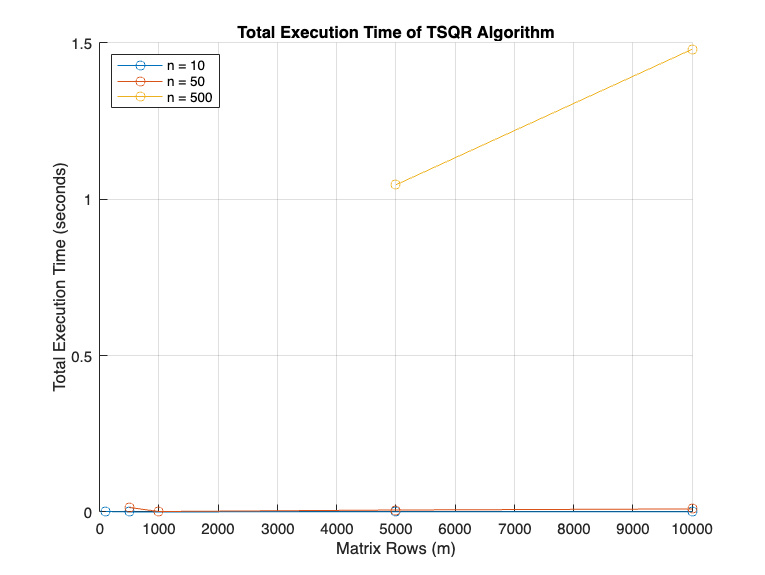

%% Scaling Performance of TSQR Algorithm
% This script reads the CSV file generated by the TSQR scaling test and
% creates scaling performance plots showing execution time, compute time,
% and communication time versus matrix size.

%% Load Data from CSV File
filename = 'scaling_results.csv';
data = readmatrix(filename);

% Separate the data columns
m_values = data(:, 1); % Matrix rows (m)
n_values = data(:, 2); % Matrix columns (n)
total_time = data(:, 3); % Total execution time (seconds)
compute_time = data(:, 4); % Compute-only time (seconds)
comm_time = data(:, 5); % Communication-only time (seconds)

% Get unique n values for grouping the plots
unique_n_values = unique(n_values);

%% Create Scaling Plot for Total Execution Time
figure;
hold on;
colors = lines(length(unique_n_values));

for i = 1:length(unique_n_values)
    n = unique_n_values(i);
    indices = (n_values == n);
    plot(m_values(indices), total_time(indices), '-o', 'DisplayName', sprintf('n = %d', n), 'Color', colors(i, :));
end

xlabel('Matrix Rows (m)');
ylabel('Total Execution Time (seconds)');
title('Total Execution Time of TSQR Algorithm');
legend('Location', 'northwest');
grid on;
hold off;
saveas(gcf, 'total_execution_time.png');

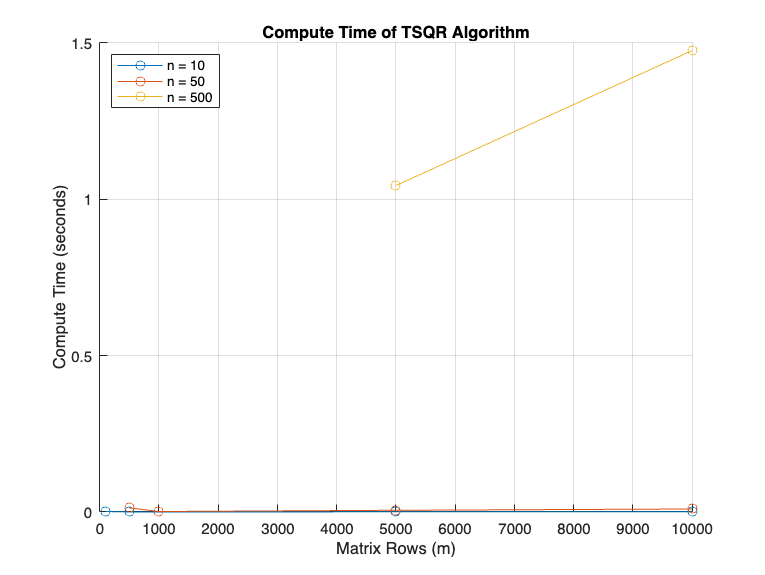


%% Create Plot for Compute Time
figure;
hold on;
for i = 1:length(unique_n_values)
    n = unique_n_values(i);
    indices = (n_values == n);
    plot(m_values(indices), compute_time(indices), '-o', 'DisplayName', sprintf('n = %d', n), 'Color', colors(i, :));
end

xlabel('Matrix Rows (m)');
ylabel('Compute Time (seconds)');
title('Compute Time of TSQR Algorithm');
legend('Location', 'northwest');
grid on;
hold off;
saveas(gcf, 'compute_time.png');

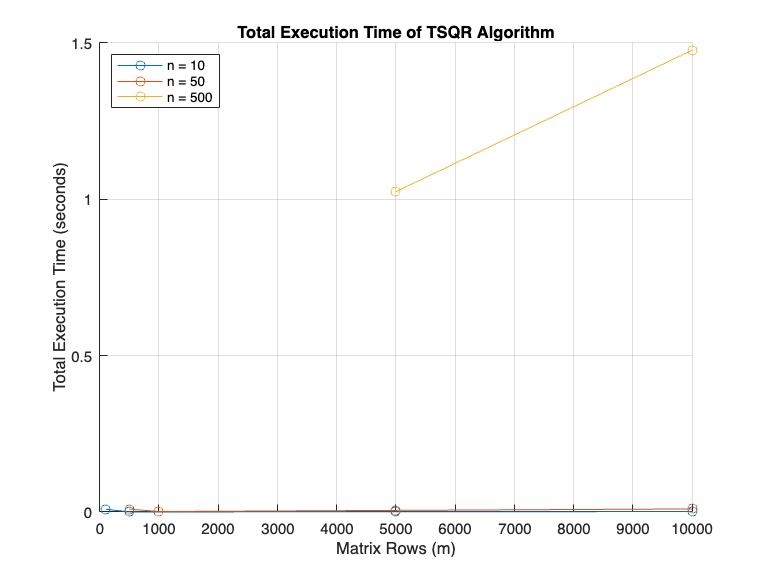


%% Create Plot for Communication Time
figure;
hold on;
for i = 1:length(unique_n_values)
    n = unique_n_values(i);
    indices = (n_values == n);
    plot(m_values(indices), comm_time(indices), '-o', 'DisplayName', sprintf('n = %d', n), 'Color', colors(i, :));
end

xlabel('Matrix Rows (m)');
ylabel('Communication Time (seconds)');
title('Communication Time of TSQR Algorithm');
legend('Location', 'northwest');
grid on;
hold off;
saveas(gcf, 'communication_time.png');


%% Display Completion Message
disp('Scaling performance plots have been saved as PNG files:');

Scaling performance plots have been saved as PNG files:


disp('- total_execution_time.png');

- total_execution_time.png


disp('- compute_time.png');

- compute_time.png


disp('- communication_time.png');

- communication_time.png
